# Abalone regression: held-out evaluation

This Live Script evaluates saved publication models through the current BANFF architecture. It reports the same task-level statistics and diagnostic plot families as the older task-specific implementation.

clearvars; close all; clc;

## Locate the publication code

evaluation_directory = fileparts(mfilename('fullpath'));
repository_root = fileparts(evaluation_directory);
addpath(repository_root, evaluation_directory);

## Choose the saved experiment family

Use the same profile and scientific overrides that were used for training.

seeds = 1:3;
profile = "main";            % main, full_rank, spsa, or neuron_sweep
overrides = struct();         % e.g. struct('N_hidden',8000) for neuron_sweep

## Choose display and export behaviour

display_options = struct();
display_options.representative_seed_index = 1;
display_options.representative_initial_condition = 1;
display_options.replay_static_spikes = true;
display_options.save_figures = false;
display_options.output_directory = fullfile(repository_root, ...
    'outputs', 'evaluation', 'abalone');

## Run held-out testing, statistics, seed audit, and plots


BANFF held-out test evaluation: abalone (main profile)
Seeds: [1 2 3]

Per-seed held-out test results
    Seed     Loss       RMSE     PearsonR    PearsonP    SignedErrorMean    SignedErrorStd    ActiveNeuronPercent
    ____    _______    ______    ________    ________    _______________    ______________    ___________________

     1      0.20366    2.0817    0.76604        0           -0.023146           2.0828              98.931       
     2      0.20291    2.0778    0.76701        0           -0.014153            2.079                96.4       
     3      0.20183    2.0723    0.76853        0           -0.036376           2.0732                93.5       

Across-seed mean and sample SD
           Met

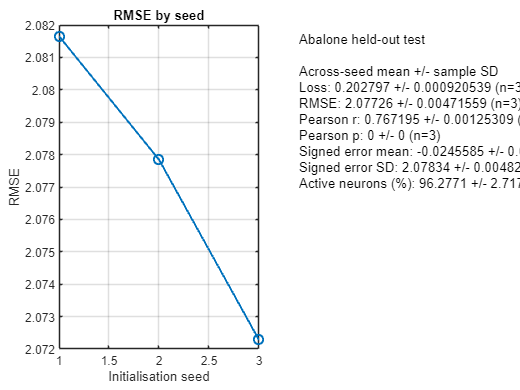

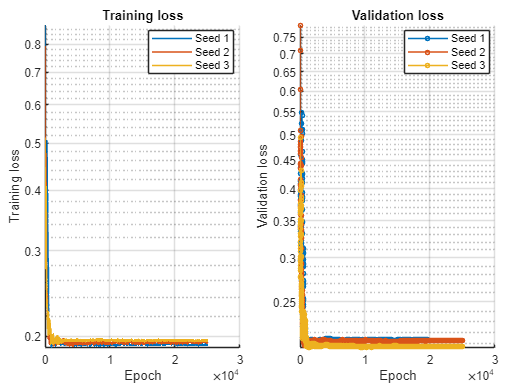

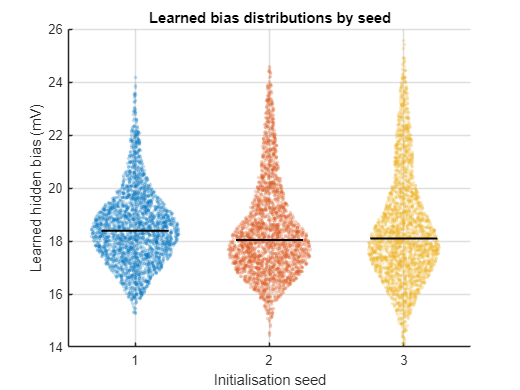

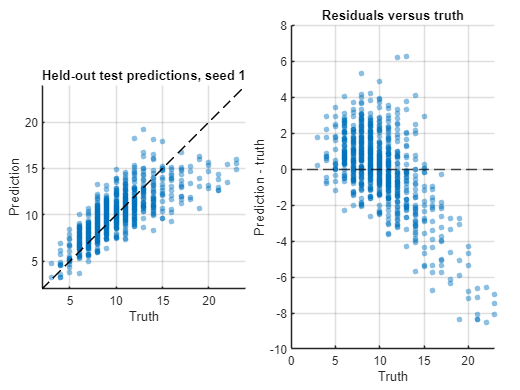

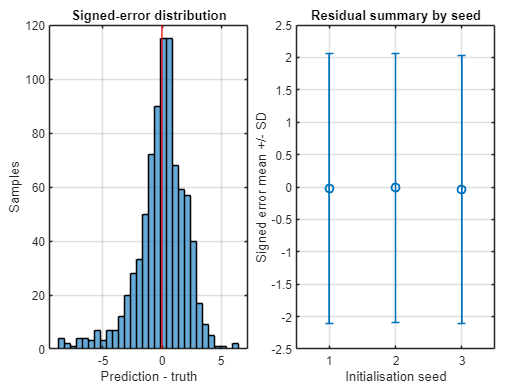

Exact full-held-out test current magnitudes (RMS over neurons, samples and time)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    ____________________    _______________    __________________    ______________________

    "Untrained"       1.9204            0.49832                0.2

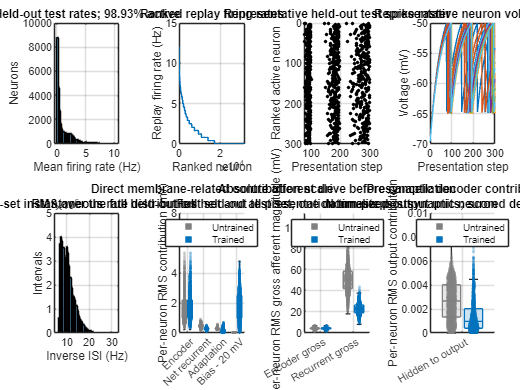

Current comparison: all 836 held-out test samples and 300 presentation steps (250800 observations per neuron and condition).


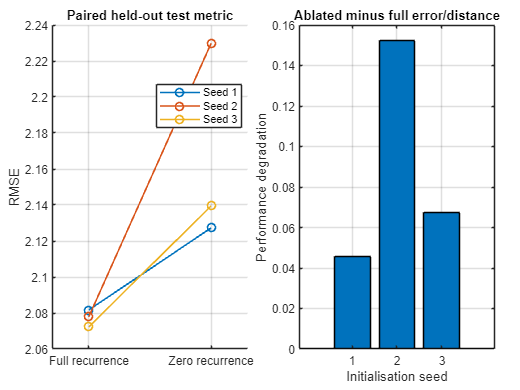

report = banff_evaluate_task("abalone", seeds, profile, overrides, display_options);

## Machine-readable results

report.seed_table

ans = 3×8 table
    Seed     Loss       RMSE     PearsonR    PearsonP    SignedErrorMean    SignedErrorStd    ActiveNeuronPercent
    ____    _______    ______    ________    ________    _______________    ______________    ___________________

     1      0.20366    2.0817    0.76604        0           -0.023146           2.0828              98.931       
     2      0.20291    2.0778    0.76701        0           -0.014153            2.079                96.4       
     3      0.20183    2.0723    0.76853        0           -0.036376           2.0732                93.5       


report.summary_table

ans = 7×4 table
           Metric              Mean        SampleSD     FiniteN
    _____________________    _________    __________    _______

    "Loss"                      0.2028    0.00092054       3   
    "RMSE"                      2.0773     0.0047156       3   
    "PearsonR"                 0.76719     0.0012531       3   
    "PearsonP"                       0             0       3   
    "SignedErrorMean"        -0.024559      0.011179       3   
    "SignedErrorStd"            2.0783      0.004825       3   
    "ActiveNeuronPercent"       96.277        2.7177       3   


report.network_seed_audit

ans = 3×4 table
    Seed                                                              ModelFile                                                                                        CheckpointHash                                                    FixedNetworkProbeHash                       
    ____    _____________________________________________________________________________________________________________________________    __________________________________________________________________    __________________________________________________________________

     1      "/home/kai.mason/Documents/BANFF_SNN_pub/outputs/models/abalone_eprop_low_rank_hard_spike_N32000_cfg448242d3ec7e_seed001.mat"    "8264a580455e51e0e150ecf05c51ced6f32bceb8e6a8e611fc4fd6331f9c34d2"    "8a03c9aaadeea75965e2aaf6a814128d01ed96aed177397bd05985505402d3f2"
     2      "